# SOM Neural Network: Wine

### Get Data

clear all; close all; clc
wine_data = load("wine.data")

wine_data = 	1.0e+03 *

    0.0010    0.0142    0.0017    0.0024    0.0156    0.1270    0.0028    0.0031    0.0003    0.0023    0.0056    0.0010    0.0039    1.0650
    0.0010    0.0132    0.0018    0.0021    0.0112    0.1000    0.0027    0.0028    0.0003    0.0013    0.0044    0.0011    0.0034    1.0500
    0.0010    0.0132    0.0024    0.0027    0.0186    0.1010    0.0028    0.0032    0.0003    0.0028    0.0057    0.0010    0.0032    1.1850
    0.0010    0.0144    0.0019    0.0025    0.0168    0.1130    0.0039    0.0035    0.0002    0.0022    0.0078    0.0009    0.0035    1.4800
    0.0010    0.0132    0.0026    0.0029    0.0210    0.1180    0.0028    0.0027    0.0004    0.0018    0.0043    0.0010    0.0029    0.7350
    0.0010    0.0142    0.0018    0.0025    0.0152    0.1120    0.0033    0.0034    0.0003    0.0020    0.0067    0.0011    0.0029    1.4500
    0.0010    0.0144    0.0019    0.0025    0.0146    0.0960    0.0025    0.0025    0.0003    0.0020    0.0053    0.0010    0.0036

X = wine_data(:, 2:end);
y = wine_data(:, 1);
X= X';
y = y';

### Dimensional reduction

w = fisher(X, y, 3);

W =     0.3365    0.0157    0.6666   -0.0855    0.0006   -0.2135    0.4397    0.1207   -0.1159   -0.0597   -0.0785    0.3977    0.0016
    0.1075    0.0928    0.4182   -0.0024   -0.0005    0.1046   -0.4006   -0.6062   -0.0393    0.1162   -0.4603   -0.1978    0.0001
    0.3467    0.0643   -0.2567   -0.0837    0.0003   -0.4373    0.2803    0.0678   -0.2202   -0.1269   -0.3281   -0.5968    0.0009


eigenv = 	1.0e+05 *

    2.1443
    0.0003
    0.0000


X = w * X;

### Capa de salida

G = gridtop(1, 3, 3);

% Center the grid in the value space aprox
mean1=mean(X(1, :));
mean2=mean(X(2, :));
G(1,:)=G(1,:)-mean(G(1,:));
G(2,:)=G(2,:)-mean(G(2,:));
G(1,:)=G(1,:)+mean1;
G(2,:)=G(2,:)+mean2;

figure;
subplot(1,2,1),plotpat(X,y);
subplot(1,2,2),plotsom(G);

### Neighborhood

neigh = linkdist(G);

### Training

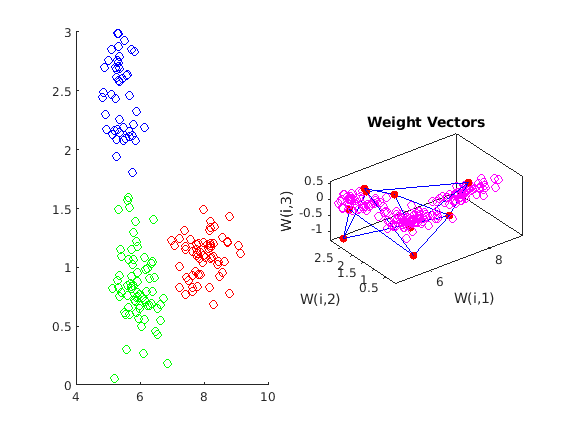

W =     5.9552    8.1276    5.7082    5.7938    7.3741    5.1976    5.4061    5.9003    5.2244
    0.8760    1.1199    2.5103    1.3732    1.0000    2.8688    2.2080    0.6819    2.6265
   -0.2741    0.2575    0.1713    0.5733   -0.4508   -1.2675    0.5290   -1.0607   -0.2624


lrate = 0.5;
max_iter = 100;
dibujar = 1;
W = KohonenTrain(X, G, neigh, lrate, max_iter)

## Clasificación distancia mínima: Distancia Euclidea

centroids_order = reorderCentroids(W, X, y);

n_classes = length(unique(y));

for i=1:n_classes
    d(i,:) = d_euclid(X,W(:, centroids_order(i)));
end

[~,yest]=min(d);
t_acierto_total_de = 100*sum(y ==yest)/length(yest)

t_acierto_total_de = 97.7528